# IOPID/FOPD max period estimating template

This is a template for estimating largest sampling period of IOPID/FOPD controller. Change the controller_type to meet your needs. From now on, We only need to maintain this script rather than two scripts. 

## Computing for FOPD or  IOPID

tic
clc;clear;
array_size=512;
controller_type='IOPID';
comment='par';
h=linspace(0.1,10,array_size); %
omega=zeros(length(h),1);
f_h=zeros(length(h),1);
% parpool(16);
parfor n=1:array_size
    fprintf('\n====Adding time stamps:%s====\n',...
        datestr(now,'yyyy/mm/dd-HH:MM:SS.FFF'));
    fprintf('Step: %d/%d\n',n,array_size);
    fprintf('Calling sub-layer function.');
%     [ omega(n),f_h(n) ]=cal_f_h(h(n));
    [ omega(n),f_h(n) ]=...
        cal_f_h_selector(h(n),controller_type);
    fprintf('Displaying results for: %s',controller_type);
    disp(['h=' num2str(h(n))]);
    disp(['f_h=' num2str(f_h(n))]);
end


====Adding time stamps:2018/10/25-16:32:57.758====

====Adding time stamps:2018/10/25-16:32:57.746====

====Adding time stamps:2018/10/25-16:32:57.782====

====Adding time stamps:2018/10/25-16:32:57.765====

====Adding time stamps:2018/10/25-16:32:57.748====

====Adding time stamps:2018/10/25-16:32:57.775====

====Adding time stamps:2018/10/25-16:32:57.753====

====Adding time stamps:2018/10/25-16:32:57.775====

====Adding time stamps:2018/10/25-16:32:57.770====

====Adding time stamps:2018/10/25-16:32:57.775====

====Adding time stamps:2018/10/25-16:32:57.763====

====Adding time stamps:2018/10/25-16:32:57.740====

====Adding time stamps:2018/10/25-16:32:57.760====

====Adding time stamps:2018/10/25-16:32:57.785====

====Adding time stamps:2018/10/25-16:32:57.787====

====Adding time stamps:2018/10/25-16:32:57.756====
Step: 2/512
Step: 4/512
Step: 6/512
Step: 8/512
Step: 10/512
Step: 13/512
Step: 17/512
Step: 22/512
Step: 28/512
Step: 35/512
Step: 44/512
Step: 55/512
Step: 69/512
Ste

toc

Elapsed time is 245.753550 seconds.


## Saving data to file

datafilename=['f_h_' controller_type '_01_100_' comment ...
    num2str(array_size)];
save([datafilename '.mat']);
fprintf('Saved data file: %s', [datafilename '.mat']);

Saved data file: f_h_IOPID_01_100_par512.mat

## Loading saved FOPD data

load f_h_FOPD_01_100_par512

## Loading saved IOPID data

load f_h_IOPID_01_100_par512

## Plotting section

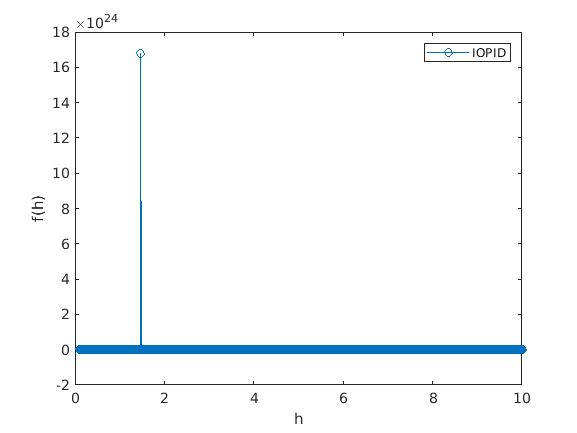

figure
plot(h,f_h,'-o');
xlabel('h');
ylabel('f(h)');
legend(controller_type);
saveas(gcf,[datafilename '.fig']);
saveas(gcf,[datafilename '.png']);

## Proving only one crosspoint

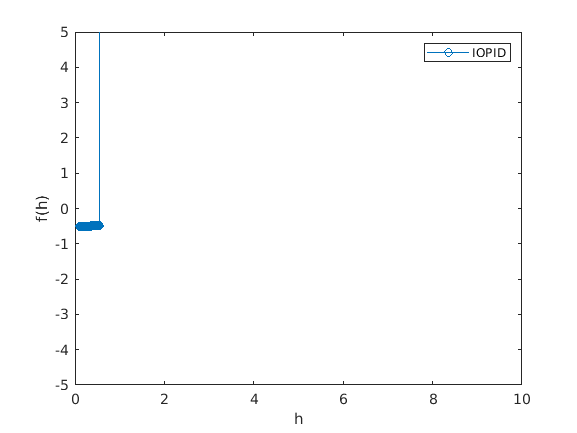

figure
plot(h,f_h,'-o');
xlabel('h');
ylabel('f(h)');
legend(controller_type);

if controller_type == 'IOPID'
    axis([0 10 -5 5]);
elseif controller_type == 'FOPD'
    axis([0 10 -5 5]);
end
saveas(gcf,[datafilename 'cross.png']);
saveas(gcf,[datafilename 'cross.fig']);

## Estimating the crosspoint

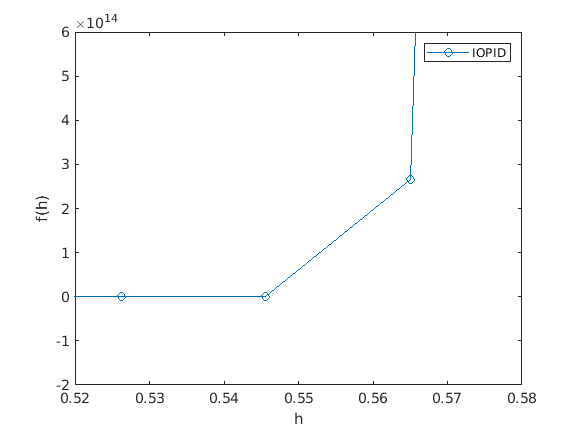

figure
plot(h,f_h,'-o');
xlabel('h');
ylabel('f(h)');
legend(controller_type);

if controller_type == 'IOPID'
    axis([0.52 0.58 -2e14 6e14]);
elseif controller_type == 'FOPD'
    axis([0.52 0.58 -2e14 6e14]);
end

saveas(gcf,[datafilename '_value.png']);
saveas(gcf,[datafilename '_value.fig']);

disp('Figure saved.')

Figure saved.
